load('1-CCRN-1-cat_Ham.mat')

load('PS_traj_2_1_C4.mat')
PS_traj_1 = PS_traj; t_traj_1 = t_traj; S_arr_1 = S_arr; S_traj_1 = S_traj;
load('PS_traj_3_1_C4.mat')
PS_traj_2 = PS_traj; t_traj_2 = t_traj; S_arr_2 = S_arr(end); S_traj_2 = S_traj;

S_arr_1

S_arr_1 =    2.013336430158567


S_arr_2

S_arr_2 =    0.221519396316761


%make sure ends match
S_traj_2 = S_traj_2 -  S_traj_2(end) +  S_traj_1(end);

poly_list = 1:4;
poly_list = poly_list';
avg2 = PS_traj_2(:,1:4)*poly_list./sum(PS_traj_2(:,1:4),2);
avg2(1)

ans =    1.107181802521788


avg2(end)

ans =    1.541669927224352


avg1 = PS_traj_1(:,1:4)*poly_list./sum(PS_traj_1(:,1:4),2);
avg1(end)

ans =    1.541669927224352


avg1(1)

ans =    2.399153821118968


pos_root_arr

ans =     0.7999    0.3106    0.1206    0.0468
    0.2001    0.0194    0.0019    0.0002
    1.9000    1.7525    1.6164    1.4909


$$pos\_root\_arr = \left(\begin{array}{cccc} 0.7999 & 0.3106 & 0.1206 & 0.0468\\ 0.2001 & 0.0194 & 0.0019 & 1.8323e-04\\ 1.9000 & 1.7525 & 1.6164 & 1.4909 \end{array}\right)$$

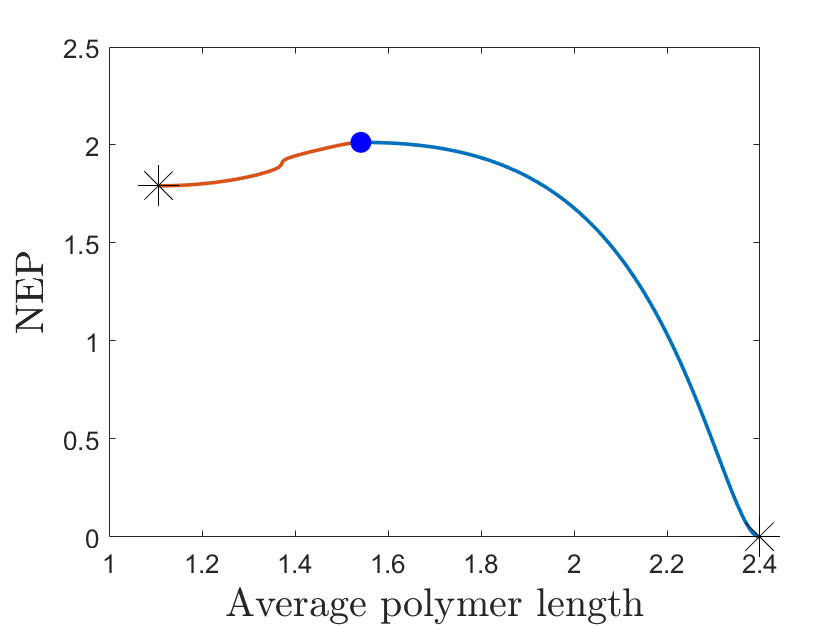

figure()
plot(avg1,S_traj_1,'LineWidth',1.8)
hold on
plot(avg2,S_traj_2,'LineWidth',1.8)
plot(avg1(1),0,'k*','MarkerSize',20)
plot(avg1(end),S_traj_1(end),'bo','MarkerSize',10,'MarkerFaceColor',"blue")
plot(avg2(1),S_traj_2(1),'k*','MarkerSize',20)
hold off
%h1=legend('Esca','Saddle','location','best');
%h1=legend('Stable','Saddle','location','best');
%set(h1,'Interpreter','latex');
%h1.FontSize = 15;
ax=gca;
ax.FontSize = 13;

xlabel('Average polymer length','interpreter','latex','FontSize',20)
ylabel('NEP','interpreter','latex','FontSize',20)

lim = double([min(pos_root_arr(:,1))-0.2  max(pos_root_arr(:,1))+0.2]);
%xlim([0.9,4.1])
lim = double([min(pos_root_arr(:,2))-0.2  max(pos_root_arr(:,2))+1]);
%ylim([0 2.1])
%grid on
%title('NEP of $\mathcal{P}_{1,4}$','Interpreter','latex','FontSize',20)

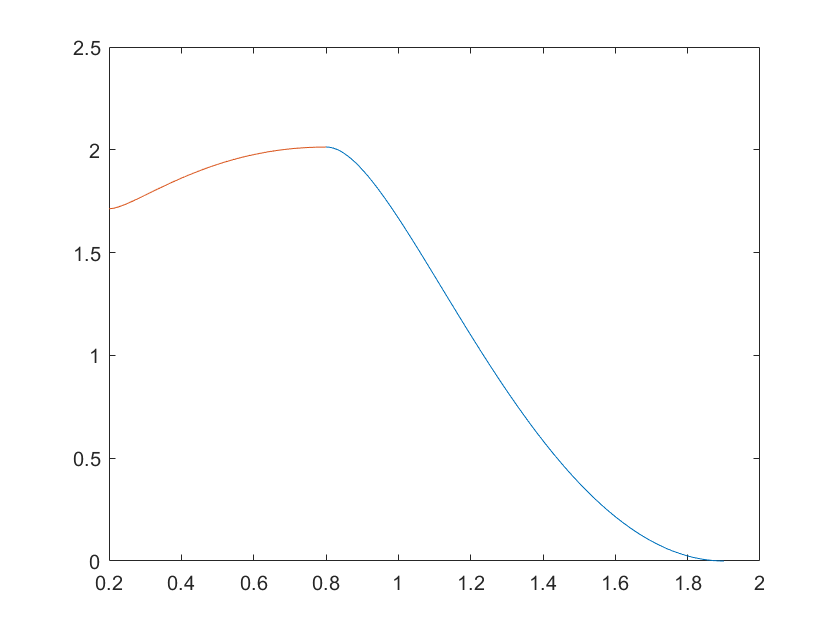

figure()
plot(PS_traj_1(:,1),S_traj_1)
hold on
plot(PS_traj_2(:,1),S_traj_2)
hold off

clust = 1:3;
figure()
plot(clust,pos_root_arr(1,:),'o')

Error using plot
Vectors must be the same length.

hold on
for i = 1:size(stab_idx,1)
    plot(clust,pos_root_arr(stab_idx(i),:),'*','MarkerSize',20)
end
for i = 1:size(sad_idx,1)
    plot(clust,pos_root_arr(sad_idx(i),:),'o')
end
hold off


figure()
%log_imp = -log(N);
plot(bin_pos,(rplus_val-rmin_val)/2500,'m--','Linewidth',0.8)
hold on
plot(bin_pos,(NEP_val-min(NEP_val)),'b','LineWidth',1.8)
yline(0,'-.','Linewidth',0.7,'color',[.7 .7 .7])
%scatter(roots,zeros(size(roots)),50,'ko')
%scatter(stab,zeros(size(stab)),50,'kx')
%scatter(rep,zeros(size(rep)),50,'k.')
%plot(bin_pos,V*(NEP_val-min(NEP_val)),'b','LineWidth',1.4)
hold off
ylim([-0.005,0.01])
xticks(floor(bin_pos(1)):1:ceil(bin_pos(end)))
legend('MAK','NEP','interpreter','latex',"FontSize",15,'location','best')
%legend('NEP','interpreter','latex',"FontSize",15)
%ylabel('Det. Velocity $\dot{q}=\partial H/ \partial p|_{p=0}$','interpreter','latex',"FontSize",15)
ylabel('NEP','interpreter','latex',"FontSize",15)
xlabel('q','interpreter','latex',"FontSize",15)
tit_str = "$\{\underline{q}\}$ = \{";
for i = 1:size(roots,2)-1
    tit_str = tit_str + string(roots(1,i)) + ", ";
end
tit_str = tit_str + string(roots(1,end)) + "\}"

title(tit_str,'interpreter','latex',"FontSize",15)
set(gca,'FontName','cmr12')
saveas(gcf,savename)
